addpath("functions/");
clear

## Data collection

save_to_file = false;

L = 50;
snapshots = 50;
wait = 0;
z = zeros(50,50);

z_snapshots = zeros(L,L,snapshots+1);
steps = 1; % Save a snapshot every 1 step

for j = 1:snapshots

	% Model to run
	BTW

	z_snapshots(:,:,j+1) = z;
end


% Cleanup workspace
clear("nn_u","nn_r", "nn_l","nn_d","d_as","l_as", ...
	"r_as","u_as","i","L_b","count","events","event_size","j")

% Save to file if the box was checked
if save_to_file; save(sprintf('data/animation_data_%s.mat', ...
		datestr(now,'mm-dd_HH-MM')), ...
		"z_snapshots","L","wait","snapshots","steps"); end

## Animate

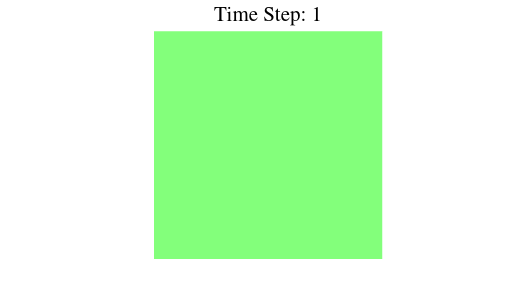

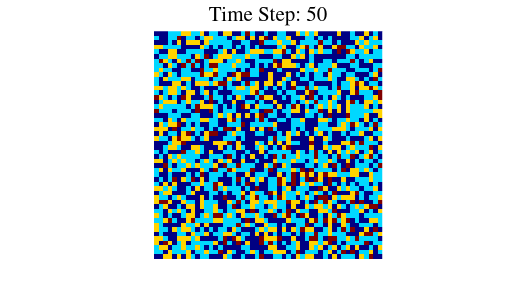

if ~exist('z_snapshots','var'); load("/home/francesco/Documents/UNI/Sistemi complessi/SOC simulation/data/animation_data_08-22_21-09.mat"); end

% Find the maximum value across all steps for proper color scaling
maxValue = max(z_snapshots(:));

% Create a figure for the animation with a specific name
figHandle = figure('Name', 'Lattice Evolution', 'NumberTitle', 'off');

% Set figure size to a larger resolution (e.g., Full HD 1920x1080)
set(figHandle, 'Position', [100, 100, 1920, 1080]);

axesHandle = axes;

% Setup the LaTeX interpreter for the title
set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 18);

% Create a VideoWriter object to save the animation as a movie
video = VideoWriter(sprintf('media/lattice_evolution-%d_steps.avi', ...
	snapshots), 'Uncompressed AVI');
video.FrameRate = 5;  % Set the frame rate (adjust as needed)
open(video);  % Open the video file for writing

% Loop over the steps to animate
for t = 1:snapshots

	% Clear previous plot
	cla(axesHandle);
	% Plot the matrix using imagesc for heatmap visualization
	imagesc(z_snapshots(:,:,t));

	% Remove the tick marks to hide grid
	set(gca, 'XTick', [], 'YTick', []);

	% Equal scaling for x and y axes
	axis equal;
	axis off;


	% Set the colormap to jet (or any other colormap you prefer)
	colormap(jet);

	% Display the color bar and adjust its properties
	cbar = colorbar;
	set(cbar, 'FontSize', 18);
	set(cbar, 'LineWidth', 2)
	ylabel(cbar, '', 'FontSize', 15);

	% Set the colorbar ticks to be integer values
	ticks = 0:1:maxValue;  % Define ticks from 0 to maxValue with step size 1
	set(cbar, 'Ticks', ticks, 'TickLabels', arrayfun(@num2str, ticks, 'UniformOutput', false));



	% Set the title and increase its font size
	title(sprintf('Time Step: %d', t), 'Interpreter', 'latex', ...
		'FontSize', 20, 'FontWeight', 'bold');


	% Capture the current frame
	frame = getframe(figHandle);

	% Write the frame to the video
	writeVideo(video, frame);

end

% Close the video file after all frames are written
close(video);